# `bh_func_calc_euler_bRg_ZYX:`

- Calculate the direction cosine matrix $\bf ^BR_G$ and the Euler rate to angular body rate matrix **A**, for a system subjected to 3 consecutive rotations

#  `Supported syntax:`

- `[bRg, A] = bh_func_calc_euler_R()`

# `Function OUTPUTS :`

- $\bf {^BR_G} $    *= f(phi, theta, psi)*

- **A         ***= g(theta, psi)* 

where:

- 
$$\bf ^Bv = {^BR_G} \enspace \times \enspace {^Gv}$$


- 
$$\matrix{
A & \times & \pmatrix{\dot{\matrix{\phi}} \cr \dot{\matrix{\theta}}  \cr \dot{\matrix{\psi}}  } & = & \pmatrix{ ^B\omega_x \cr ^B\omega_y \cr ^B\omega_z} 

}$$


- phi, theta, psi are SYM variables

# `Description:`

Say we have a fixed/inertial **G-frame** and we have a body **B-frame**. We start by having our B-frame co-incident with G, and then we start to rotate the B-frame. Specifically, we're going to apply 3 LOCAL axes rotations which will result in a newly orientated B-frame.  Assume that we apply these 3 successive rotations in the following order:

- R1Z occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- R2Y occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- R3X occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

We can express a vector defined in the G axis to it's corresponding description in the B axis, using a sequence of **PASSIVE** rotation matrices, ie:

-    $\bf ^Bv = R3X(\psi_x) \enspace \times \enspace 
R2Y(\theta_y) \enspace \times \enspace R1Z(\phi_z) \enspace \times \enspace {^Gv}$        OR, in a more compact form as:

-    
$$\bf ^Bv = {^BR_G} \enspace \times \enspace {^Gv}$$


Also, we can relate the Euler rates to the angular BODY rates via the following:

- 
$$\matrix{
A & \times & x & = & b \cr
\downarrow & & \downarrow & & \downarrow \cr
A & \times & \pmatrix{\dot{\matrix{\phi}} \cr \dot{\matrix{\theta}}  \cr \dot{\matrix{\psi}}  } & = & \pmatrix{ ^B\omega_x \cr ^B\omega_y \cr ^B\omega_z} 

}$$


function [bRg, A] = bh_func_calc_euler_bRg_ZYX()

## Review the concept of PASSIVE rotation matrices :

Consider the following scenario: 

- We have a data point $P$.

- We have a fixed frame called the **G-fame.**

- We know the *(x,y) *co-ordinates of the point $P$ in this **G-fame** and refer to this as ${^GP}$.

- We then rotate the **B-frame** by $\theta$ relative to the fixed **G-frame**. 

We now want to know what the co-ordinate of the point $P$ is relative to this new **B-frame, **ie: what is ${^BP}$ ?  This scenario is shown in the figure below:

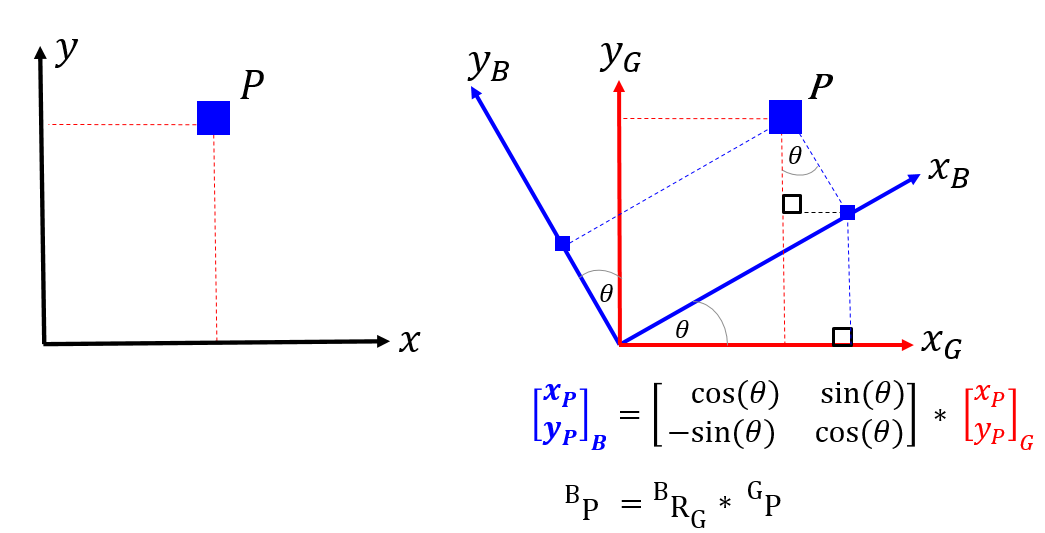 

A **PASSIVE** rotation matrix, converts the co-ordinates of a point expressed in a fixed **G-frame**, into the co-ordinates of the same point expressed in the new **B-frame**. 

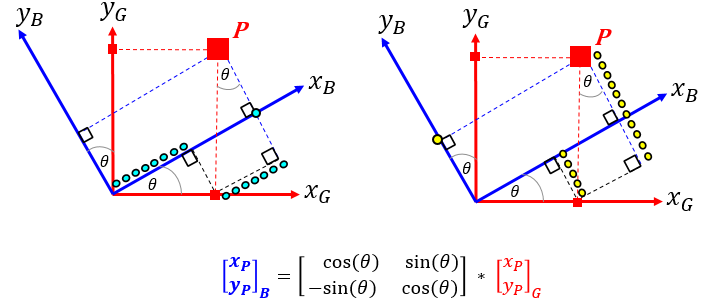

## An example of 3 successive PASSIVE rotations

Say we have a fixed G-frame. We start by having our B-frame co-incident with G, and then we start to rotate the B-frame. Specifically, we're going to apply 3 LOCAL axes rotations which will result in a newly orientated B-frame.  Assume that we apply these 3 successive rotations in the following order:

- R1Z occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- R2Y occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- R3X occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

We can express a vector defined in the G axis to it's corresponding description in the B axis, using a sequence of **PASSIVE** rotation matrices, ie:

- $\bf ^Bv = R3X(\psi_x) \enspace \times \enspace 
R2Y(\theta_y) \enspace \times \enspace R1Z(\phi_z) \enspace \times \enspace {^Gv}$         OR, in a more compact form as:

- 
$$\bf ^Bv = {^BR_G} \enspace \times \enspace {^Gv}$$


## Create a passive rotation object

%syms phi theta psi
phi   = sym('phi');
theta = sym('theta');
psi   = sym('psi');

OBJ_P = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, [phi, theta, psi], 'SYM');

## Here are the PASSIVE rotation matrices:

Here's  $\bf  R1Z(\phi_z) $:

R1Z = OBJ_P.get_R1;

Here's $\bf 
R2Y(\theta_y) $:

R2Y = OBJ_P.get_R2;

Here's $\bf R3X(\psi_x) $

R3X = OBJ_P.get_R3;

## Calculate the Direction Cosine Matrix  ${^{B}}R_G $

Recall we earlier said:          

-    $\bf ^Bv = R3X(\psi_x) \enspace \times \enspace 
R2Y(\theta_y) \enspace \times \enspace R1Z(\phi_z) \enspace \times \enspace {^Gv}$        OR, in a more compact form as:

-    
$$\bf ^Bv = {^BR_G} \enspace \times \enspace {^Gv}$$


bRg = R3X * R2Y * R1Z;

## Explore the relationship between BODY rates and EULER rates

As we apply these local frame rotations of ($\phi, \theta, \psi$), we can represent the **angular rates** ($\dot{\phi}, \dot{\theta}, \dot{\matrix{\psi}}$) of the rotating frames into the LOCAL frame co-ordinates. These local frame co-ordinates can then be converted into co-ordinates expressed in the final B frame.  For example, during each of the local axes rotations we can think of there being a START frame and an END frame:

      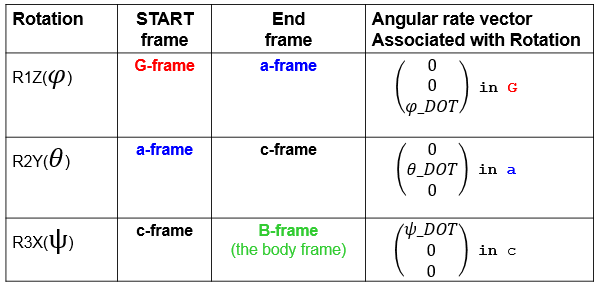    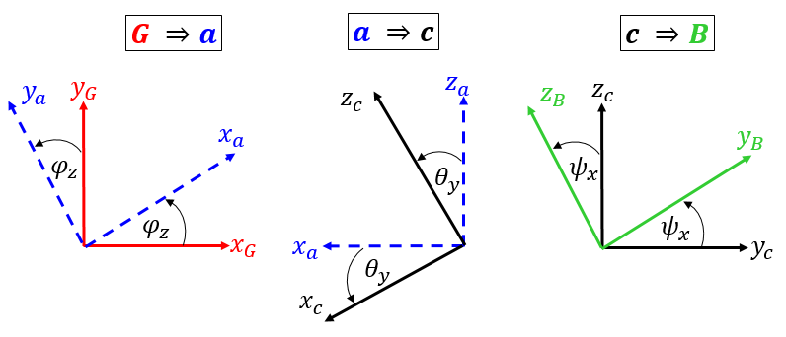

We can express each of the local frame angular velocities into their corresponding components in the final B frame - and we'll use PASSIVE rotation matrices to do this:

syms phi_dot  theta_dot  psi_dot

aRg = R1Z;
cRa = R2Y;
bRc = R3X;

Here's the portion of the BODY frame rate associated with our $\dot{ \matrix{\phi}}$ rate:

wb_part_1 = bRc * cRa * aRg * [0;0;phi_dot];   % convert local G into B

Here's the portion of the BODY frame rate associated with our $\dot{ \matrix{\theta}}$ rate:

wb_part_2 = bRc * cRa *       [0;theta_dot;0]; % convert local a into B

Here's the portion of the BODY frame rate associated with our $\dot{ \matrix{\psi}}$ rate:

wb_part_3 = bRc *             [psi_dot;0;0];   % convert local c into B

## The total angular velocity expressed in the BODY B frame is therefore

We can now construct the total angular velocity vector expressed in components of the final B frame.

-    
$$_G^{B}\omega_b \equiv \omega_b = f( \dot{ \matrix{\phi}}, \dot{ \matrix{\theta}}, \dot{ \matrix{\psi}}, \phi, \theta, \psi) $$
 

wb = wb_part_1 + wb_part_2 + wb_part_3;

## We can write the angular velocity vector $\omega_b$ as a MATRIX equation

Let's say that:  $ \omega_b = \pmatrix{p \cr q \cr r}
$, we can write a matrix equation of the form **A.x = b** that describes the relationship between the body rates $\omega_b$ and the Euler rates:  $A \times   \pmatrix{ \phi_{dot} \cr \theta_{dot} \cr \psi_{dot} }  =  \pmatrix{p \cr q \cr r}  $  

syms p q r

x = [ phi_dot   ;
      theta_dot ;
      psi_dot    ];
    
[A,b] = equationsToMatrix(  wb(1)==p, ...
                            wb(2)==q, ...
                            wb(3)==r, ...
                            x); 

Just to clarify this, let me put each of the 3 elements side by side as  [**A, x, b] ,** where:


$$\matrix{
A & \times & x & = & b \cr
\downarrow & & \downarrow & & \downarrow \cr
A & \times & \pmatrix{\dot{\matrix{\phi}} \cr \dot{\matrix{\theta}}  \cr \dot{\matrix{\psi}}  } & = & \pmatrix{ ^B\omega_x \cr ^B\omega_y \cr ^B\omega_z} 

}$$


end